- Ch-ka Nyquista

- Zapas modułu i fazy

- Przedstawić wpływ zmian** Kp** zmiane ch-ki Nyquista 

- Przedstawić wpływ zmian** fc** zmiane ch-ki Nyquista, fc - f. odcięcia filtru pomiarowego 

- Zapas modułu i fazy przy pominiętym filtrze pomiarowym

clc
clear

syms s H_pid(s) H_ob(s) H_filtr(s) H_sys(s) H_sys(w) jw j w
sympref('FloatingPointOutput',true);

%% Stałe
% J - m. bezw. wału silnika
% masa obciążenia mL, rL, promień koła obiązenia
Km = 0.0257;     % [V/(rad*sek)]
Rm = 2.675;      % [Ohm]
J  = 9.63e-6;    % [kg*m^2]
mL = 0.033;      % [kg]
rL = 0.0262;     % [m]
JL = mL * rL^2;
Jeq= JL + J;

Kp = 0.03;
Ti = 0.2;
Td = 0.0007; 

w_filtr = 10;

### Z filtrem


%% PID
H_pid(s) = Kp*( 1 + 1/Ti * 1/s + Td * s)

$$H\_pid(s) = 2.1000e-05\,s+\frac{0.1500}{s}+0.0300$$

disp('Transmitancja PID szereg. rowno.')

Transmitancja PID szereg. rowno.


H_pid(s) = collect(H_pid)

$$H\_pid(s) = \frac{21\,s^{2}+30000\,s+150000}{1000000\,s}$$

%% OBIEKT BEZ TARCIA
H_ob(s) = Km/Rm * 1/(Jeq * s + Km^2/Rm)

$$H\_ob(s) = \frac{0.0096}{3.2283e-05\,s+2.4691e-04}$$

%% FILTR 
H_filtr(s) = 1/(w_filtr^(-1)*s + 1)

$$H\_filtr(s) = \frac{1}{0.1000\,s+1}$$

%% Transmitancja otwartej pętli do nyquista
H_sys(s) = H_pid(s) * H_ob(s) * H_filtr(s)

$$H\_sys(s) = \frac{9.6075e-09\,\left(21\,s^{2}+30000\,s+150000\right)}{s\,\left(0.1000\,s+1\right)\,\left(3.2283e-05\,s+2.4691e-04\right)}$$

H_sys(s) = collect(H_sys(s), s)

$$H\_sys(s) = \frac{1.2445e+22\,s^{2}+1.7778e+25\,s+8.8890e+25}{1.9912e+23\,s^{3}+3.5142e+24\,s^{2}+1.5230e+25\,s}$$

H_sys_bez_f(s) = H_pid(s) * H_ob(s)

$$H\_sys\_bez\_f(s) = \frac{9.6075e-09\,\left(21\,s^{2}+30000\,s+150000\right)}{s\,\left(3.2283e-05\,s+2.4691e-04\right)}$$

H_sys_bez_f(s) = collect(H_sys_bez_f(s), s)

$$H\_sys\_bez\_f(s) = \frac{6.2223e+21\,s^{2}+8.8890e+24\,s+4.4445e+25}{9.9561e+23\,s^{2}+7.6149e+24\,s}$$


H_sys(w) = H_sys(j*w)

$$H\_sys(w) = \frac{1.2445e+22\,j^{2}\,w^{2}+1.7778e+25\,j\,w+8.8890e+25}{1.9912e+23\,j^{3}\,w^{3}+3.5142e+24\,j^{2}\,w^{2}+1.5230e+25\,j\,w}$$

H_sys(w) = subs(H_sys, j, 1j)

$$H\_sys(w) = -\frac{-1.2445e+22\,w^{2}+1.7778e+25\,w\,\mathrm{i}+8.8890e+25}{1.9912e+23\,w^{3}\,\mathrm{i}+3.5142e+24\,w^{2}-1.5230e+25\,w\,\mathrm{i}}$$

H_sys_bez_f(w) = H_sys_bez_f(j*w)

$$H\_sys\_bez\_f(w) = \frac{6.2223e+21\,j^{2}\,w^{2}+8.8890e+24\,j\,w+4.4445e+25}{9.9561e+23\,j^{2}\,w^{2}+7.6149e+24\,j\,w}$$

H_sys_bez_f(w) = subs(H_sys_bez_f, j, 1j)

$$H\_sys\_bez\_f(w) = \frac{-6.2223e+21\,w^{2}+8.8890e+24\,w\,\mathrm{i}+4.4445e+25}{-9.9561e+23\,w^{2}+7.6149e+24\,w\,\mathrm{i}}$$


w_in = [-30:0.1:-1, 1:0.1:30];
vals = double(H_sys(w_in));
vals_bez_f = double(H_sys_bez_f(w_in));

vals(1:4).'

ans =   -0.0839 + 0.0381i
  -0.0844 + 0.0385i
  -0.0849 + 0.0388i
  -0.0853 + 0.0392i


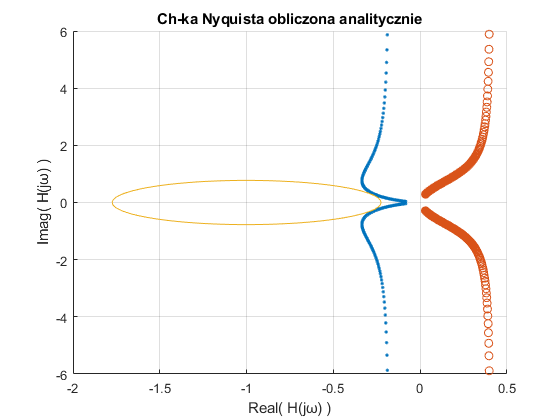


vals_re = real(vals);
vals_im = imag(vals);
vals_re_bez_f = real(vals_bez_f);
vals_im_bez_f = imag(vals_bez_f);

figure(1); hold on; grid on;
% xlim([-1 1])
% ylim([-1 1])
scatter(vals_re, vals_im, '.');
scatter(vals_re_bez_f, vals_im_bez_f, 'o')

title('Ch-ka Nyquista obliczona analitycznie')
xlabel('Real( Η(jω) )')
ylabel('Imag( Η(jω) )')

r=0.6;
fimplicit( @(x,y) (x+1).^2 + y.^2 - r )

hold off;

## Sprawdzenie

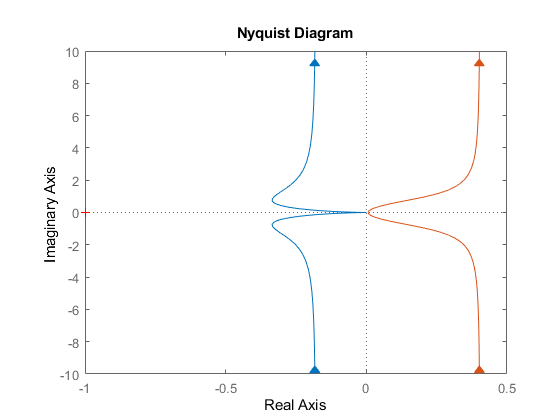

s = tf('s');

H_pid = Kp*( 1 + 1/Ti * 1/s + Td * s);
H_ob = Km/Rm * 1/(Jeq * s + Km^2/Rm);
H_filtr = 1/(w_filtr^(-1)*s + 1);

H_sys_otwarte = H_pid * H_ob * H_filtr;
H_sys_otwarte_bez_f = H_pid * H_ob;

figure(2); hold on;
nyquist(H_sys_otwarte)
nyquist(H_sys_otwarte_bez_f)
hold off;